clc, clear, close all;

## Load data

base_sample_rate = 1000;
emg_sample_rate = 1000;

AddPaths()

Linux


% "column": ["index", "overbodig", "sync", "spier 1", "spier 2"]

emg_file = 'EMG_SECOND_PLAY_CHOPIN_C.txt';
data = readmatrix(emg_file, 'Range', 4, 'Delimiter', '\t');
mV_muscle1 = data(:, 4);

emg_file = 'EMG_MVC_001.txt';
data = readmatrix(emg_file, 'Range', 4, 'Delimiter', '\t');
mvc_muscle1 = data(:, 4);

## Convert to mV

n = 12; VCC = 3; Gemg = 1000;
DigTomV = @(adc) (((adc./2.^n - 1/2) .* VCC) ./ Gemg) * 1000;
x_start = 50550; samples = 100; x_stop = x_start+samples;

mV_muscle1 = DigTomV(mV_muscle1(x_start:x_stop)');
mV_mvc1 = DigTomV(mvc_muscle1');

## Filter data

### Settings

f_low = 10;     % Lower cutoff frequency
f_high = 250;   % Upper cutoff frequency
freq_range = [f_low/(emg_sample_rate/2), f_high/(emg_sample_rate/2)];
filter_order = 3;

### Bandpass filters

% Design the Butterworth bandpass filter
[b{1},a{1}] = butter(filter_order, [f_low/(emg_sample_rate/2), f_high/(emg_sample_rate/2)], 'bandpass');
[b{2},a{2}] = cheby1(filter_order, 6, [f_low/(emg_sample_rate/2), f_high/(emg_sample_rate/2)], 'bandpass');
[b{3},a{3}] = cheby2(filter_order, 6, [f_low/(emg_sample_rate/2), f_high/(emg_sample_rate/2)], 'bandpass');
[b{4},a{4}] = ellip(filter_order, 1, 6, [f_low/(emg_sample_rate/2), f_high/(emg_sample_rate/2)], 'bandpass');

### Bandpass filters

% Design the Butterworth bandpass filter
% [b{1},a{1}] = butter(filter_order, f_high/(emg_sample_rate/2), 'low');
% [b{2},a{2}] = cheby1(filter_order, 6, f_high/(emg_sample_rate/2), 'low');
% [b{3},a{3}] = cheby2(filter_order, 6, f_high/(emg_sample_rate/2), 'low');
% [b{4},a{4}] = ellip(filter_order, 1, 6, f_high/(emg_sample_rate/2), 'low');

### filter vs filtfilt

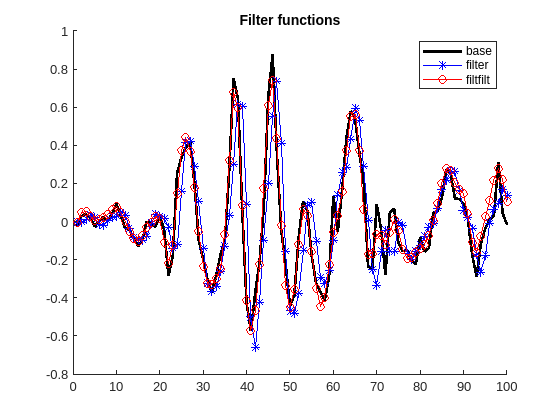

f_x = filter(b{1},a{1},mV_muscle1);
ff_x = filtfilt(b{1},a{1},mV_muscle1);

figure; hold on
plot(mV_muscle1, 'k', 'LineWidth', 2);
plot(f_x, '*b-', 'LineWidth', 1);
plot(ff_x, 'or-', 'LineWidth', 1);

xlim([0, samples])
title("Filter functions");
legend("base", "filter", "filtfilt");
hold off

### Plot filters

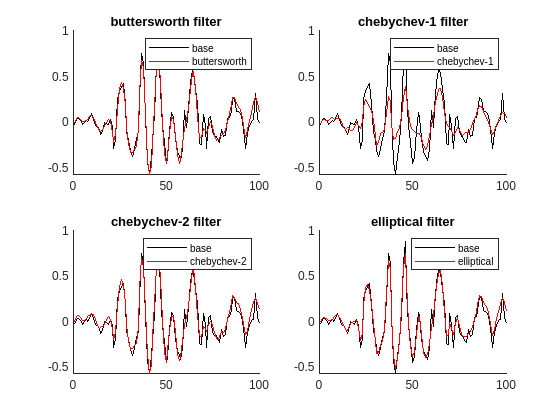

figure;

titles = ["buttersworth", "chebychev-1", "chebychev-2", "elliptical"];
filter_amount = length(titles);

for k = 1:filter_amount
    ff_x = filtfilt(b{k},a{k},mV_muscle1);

    subplot(2,2,k); hold on
    plot(mV_muscle1, 'k', 'LineWidth', 1);
    plot(ff_x, 'r', 'LineWidth', 1);

    legend("base", titles(k));
    xlim([0, samples])
    title(titles(k) + " filter");
    hold off
end

### Bode plots

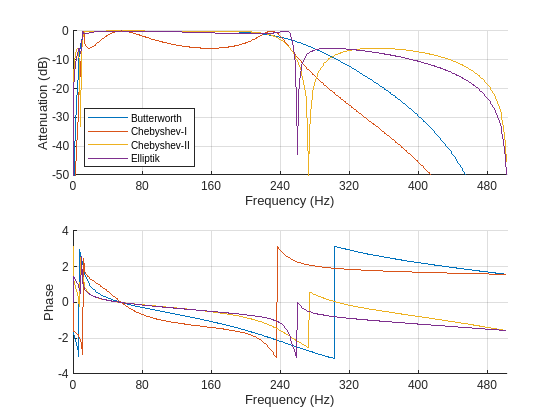

for k = 1:filter_amount
    [h{k},w{k}] = freqz(b{k},a{k});
end

figure

subplot(2,1,1); hold on
for k = 1:filter_amount
    plot(w{k},20*log10(abs(h{k})))
end
hold off; grid
xticklabels(0:80:480);
xlim([0 pi]); ylim([-50 0]);
xlabel('Frequency (Hz)');
ylabel('Attenuation (dB)');
legend('Butterworth','Chebyshev-I','Chebyshev-II','Elliptik', 'Location','southwest');

subplot(2,1,2); hold on
for k = 1:filter_amount
    plot(w{k},angle(h{k}))
end
hold off; grid
xticklabels(0:80:480);
xlim([0 pi]);
xlabel('Frequency (Hz)');
ylabel('Phase');



% phase problems get removed due to filtfilt function
% kijk na of eerst bandpass of eerst enveloping beter is (peak in 0)
% https://dsp.stackexchange.com/questions/55953/chebyshev-i-or-chebyshev-ii
% https://analogcircuitdesign.com/butterworth-and-chebyshev-filters/